## Caricamento dati

root = "C:\Users\trima\OneDrive - unime.it\Appunti Università\Appunti condivisi\00) Tirocinio\Trimarchi\V2G-with-Regression-Learner-and-LSTM-NN";
% Aggiungiamo il percorso degli script
addpath(root + "\Scripts");
%zone_id=1; %"Zone_509_Ponte Mammolo";
%zone_id=2; %"Zone_116_Trastevere";
%fzone_id=3; %"Zone_125";
%zone_id=4; %"Zone_705_Prenestino-Centocelle";;
%zone_id=5; %"Eur 1201"
%zone_id=6;
%zone_id=7; %"Zone_906_Arco_Di_Travertino"
zone_id=8; % Zona 1016
%zone_id=9; %Zona 214 Trieste
%zone_id=10; % Zona 2004
%zone_id=11; % Zona 2002
%zone_id=12; %Torvergata

% Usiamo uno script che vuole come parametro la root e la zona da caricare
data = load_datas(root,zone_id);

Dati per la zona "Zone_1016_Anagnina" caricati correttamente.


## Costanti

num_lags = 48;
predittori = {'AAC_energy','precipprob','temp','windspeed', 'holiday_indicator'};
target = 'AAC_energy';
colonne_da_normalizzare = [predittori, target];

[data_norm, params_norm] = normalize_zscore_2(data, colonne_da_normalizzare);

Normalizzazione Z-score completata sull'intero dataset.


[Xdatas, Ydatas, time_vector_datas] = create_lags_LSTMNN(data_norm, num_lags, predittori, target);

Giorni totali: 58
Giorni consecutivi validi: 54
Lunghezza sequenza (num_predittori): 48
Numero di feature: 5
Numero di target: 1
Numero di sequenze create: 2592
Creazione sequenze LSTM completata


rete = models.net_2025_11_04_20_19_54.net;
dati_predizione = Xdatas;

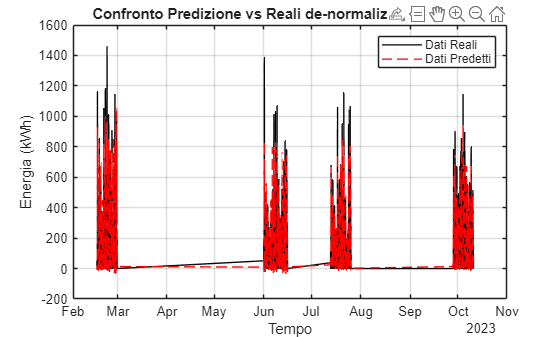

predizione_fig =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [423 230 560 337.3557]
       Units: 'pixels'

  Show all properties


predizione = minibatchpredict(rete, dati_predizione);
predizione_fig = get_plot(predizione, Ydatas, params_norm, target, time_vector_datas)

indicatori_predizione = get_indicators(predizione, Ydatas);